# Fixed Manipulator

## Geometric model

robot_angles = [0 0 0 0 0 0 0];
[T, A01, A12, A23, A34, A45, A56, A67] = GeometricPanda(robot_angles)

T =     1.0000         0         0    0.0880
         0   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000    0.9260
         0         0         0    1.0000


A01 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


A12 =     1.0000         0         0         0
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.3330
         0         0         0    1.0000


A23 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


A34 =     1.0000         0         0    0.0825
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    0.3160
         0         0         0    1.0000


A45 =     1.0000         0         0   -0.0825
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


A56 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    0.3840
         0         0         0    1.0000


A67 =     1.0000         0         0    0.0880
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


## Differential Analitic model

[x,R,J] = kinmodel_panda(robot_angles)

x =     0.0880
         0
    0.9260


R =      1     0     0
     0    -1     0
     0     0    -1


J =          0    0.5930         0   -0.2770         0    0.1070         0
    0.0880         0    0.0880         0    0.0880         0         0
         0   -0.0880         0    0.0055         0    0.0880         0
         0         0         0         0         0         0         0
         0    1.0000         0   -1.0000         0   -1.0000         0
    1.0000         0    1.0000         0    1.0000         0   -1.0000


## MATLAB Franka Panda model

robot = importrobot('frankaEmikaPanda.urdf')

robot =   rigidBodyTree with properties:

     NumBodies: 11
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'panda_link1'  'panda_link2'  'panda_link3'  'panda_link4'  'panda_link5'  'panda_link6'  'panda_link7'  'panda_link8'  'panda_hand'  'panda_leftfinger'  'panda_rightfinger'}
      BaseName: 'panda_link0'
       Gravity: [0 0 0]
    DataFormat: 'struct'


% set configuration
config = homeConfiguration(robot)

config = 1×9 struct array with fields:
    JointName
    JointPosition


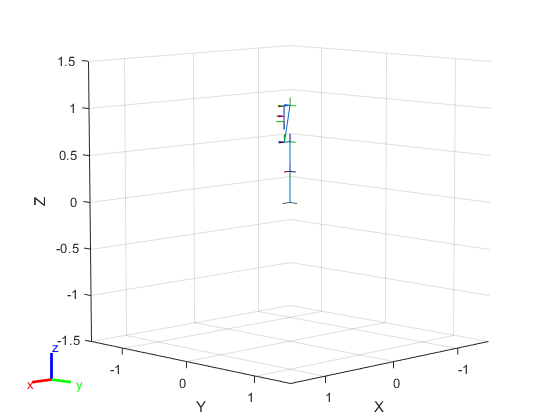

config(4).JointPosition = 0;
show(robot,config); 

## Robot toolbox DH model

% this is a classic (Spong?) DH convention parameters table, on official Franka
% Emika site there is a different (Craig) convention (that is a pain in the
% arse)

% | a | alpha | d | theta-0 (ignored) |
dhparams = [0 -pi/2 0.333 0 ;
               0 pi/2 0 0 ;
               0.0825 pi/2 0.316 0 ;
               -0.0825 -pi/2 0 0 ;
               0 pi/2 0.384 0 ;
               0.088 pi/2 0 0 ;
               0 0 0.107 0]

dhparams =          0   -1.5708    0.3330         0
         0    1.5708         0         0
    0.0825    1.5708    0.3160         0
   -0.0825   -1.5708         0         0
         0    1.5708    0.3840         0
    0.0880    1.5708         0         0
         0         0    0.1070         0


robot = rigidBodyTree;

% joint 1
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;
addBody(robot,body1,'base')

% joint 2
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,dhparams(2,:),'dh');
body2.Joint = jnt2;
addBody(robot,body2,'body1')

% joint 3
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
setFixedTransform(jnt3,dhparams(3,:),'dh');
body3.Joint = jnt3;
addBody(robot,body3,'body2')
 
% joint 4
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
setFixedTransform(jnt4,dhparams(4,:),'dh');
body4.Joint = jnt4;
addBody(robot,body4,'body3')

% joint 5
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
setFixedTransform(jnt5,dhparams(5,:),'dh');
body5.Joint = jnt5;
addBody(robot,body5,'body4')

% joint 6
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
setFixedTransform(jnt6,dhparams(6,:),'dh');
body6.Joint = jnt6;
addBody(robot,body6,'body5')

% joint 7
body7 = rigidBody('body7');
jnt7 = rigidBodyJoint('jnt7','revolute');
setFixedTransform(jnt7,dhparams(7,:),'dh');
body7.Joint = jnt7;
addBody(robot,body7,'body6')

% set configuration
config = homeConfiguration(robot)

config = 1×7 struct array with fields:
    JointName
    JointPosition


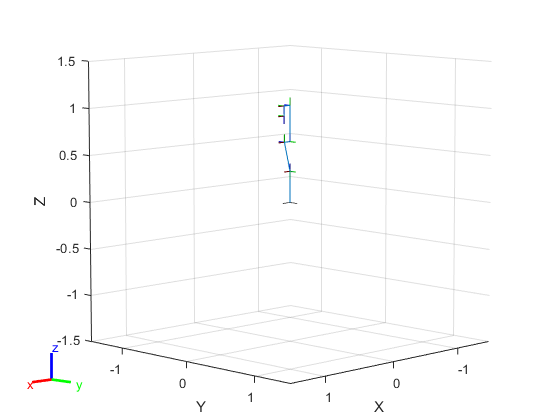

% config(3).JointPosition = -pi/2;

% showdetails(robot)
% figure(Name="Franka Emika Panda") 

% show robot
show(robot,config);

% get transforms (in global TF)
transformBase = getTransform(robot, config, ['base'])

transformBase =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


transform3 = getTransform(robot, config, ['body3'])

transform3 =     1.0000         0         0    0.0825
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    0.6490
         0         0         0    1.0000


transformEE = getTransform(robot, config, ['body7'])

transformEE =     1.0000         0         0    0.0880
         0   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000    0.9260
         0         0         0    1.0000


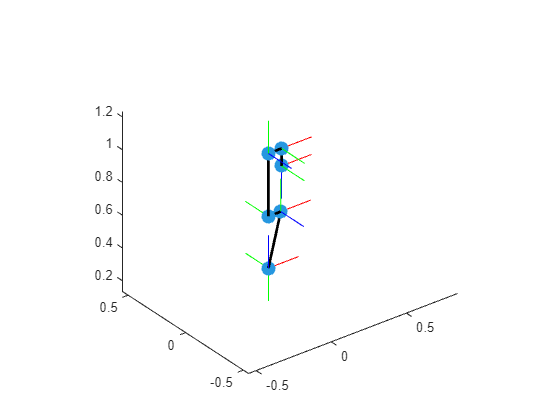

% create a list of transforms
robot_transforms = [];
for i = 1:1:size(dhparams,1)
    robot_transforms(:,:,i) = getTransform(robot, config, ['body'+string(i)]);
end

% display robot
figure()
axis equal
showPanda(robot_transforms)


% hold on
% plotTransforms(transformEE(1:3,4)',rotm2quat(transformEE(1:3,1:3)),'FrameSize',1)